
$$\begin{array}{l}
\text{ECSE}\text{ }307-\text{Winter}\text{ }2018\text{                                                                                                        }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{           }\text{ }\text{Professor}\text{ }\text{Aditya}\text{ }\text{Mahajan}\\
\text{                                                                                                                         }\text{ }\text{ }\text{ }\text{                       }\text{ }\text{TA}:\text{Mohammad}\text{ }\text{Afshari}\text{ }\text{and}\text{ }\text{Anas}\text{ }\text{El}\text{ }\text{Fathi}
\end{array}$$


# 
$$\text{Lab}\text{ }6$$


# 
$$\text{Desigining}\text{ }\text{Speed}\text{ }\text{Estimator}\text{ }\text{for}\text{ }\text{DC}\text{ }\text{Mot}\mathrm{or}$$


%* Fill in your group number----------------------------------------------%
GroupeNum = 19;
%* Fill in your student Name and ID--------------------------------------*%
Students(1).Name = 'Yassine Douida';
Students(1).ID = '260741964';
Students(2).Name = 'Nayem Alam';
Students(2).ID = '260743549';
%-------------------------------------------------------------------------%

## **0. Objectives**

In this lab, we will use observations from the DC Motor to estimate the angular velocity and the current of the DC Motor. We use the state space model from Lab05. First, using the state space model from Lab05, we design an estimator gain for the discrete time system such that the estimated value follow the states. Second, we run the motor with a pre-defined input (open loop and closed loop) and estimate the speed as well as the current, observing only angular velocity as the output.

To verify that the hardware is working, run the following (You can ignore the warnings, but you shouldn't have any errors). Kepp in mind that you have to have both of Lab06 and QnectDCMotor in the same directory.

Motor = QnetDCMotor();

## **1. Review of the state space representation of DC Motor**

Recall from Lab05 that the dynamics of DC motor can be written in state space form as 


$$ J \frac{d \omega}{dt} + b \omega = K_t i $$



$$ L \frac{d i}{dt} + R i = v - K_e \omega $$


A schematic of a DC motor is shown in the following

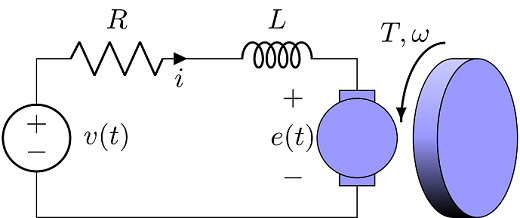

where the parameters are defined as follow

Param.Kt = 0.034; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
Param.Ke = 0.034; % Back electromotive proportionality constant (V/rad/s)
Param.L = 0.018; % Electric inductance (H)
Param.R = 8.4; % Terminal resistance (Ohm)
Param.J = 2e-05; % Rotor moment of inertia (kg.m2)
Param.b = 1e-06; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

Like Lab05, we can write the state space representation of the DC Motor as follows.

A = [-Param.b/Param.J,Param.Kt/Param.J;-Param.Ke/Param.L,-Param.R/Param.L];
B = [0;1/Param.L];
C = [1,0]

C =      1     0


D = 0;

## *Question 1 (1.5 mark)*

In `MATLAB`, construct the state space representation of the continous time as well as the discrete time system. For the dicrete time state space use `c2d(sys,Ts,method)` with method to be*** zero order hold (zoh)*** and $T_S =\mathrm{dt}=0\ldotp 01$.

% Write your code here
% Using the given A,B,C,D

Ts = 0.01;
%state space (continuos)
Go = ss(A,B,C,D) 


Go =
 
  A = 
           x1      x2
   x1   -0.05    1700
   x2  -1.889  -466.7
 
  B = 
          u1
   x1      0
   x2  55.56
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



%state space (discrete)
Gd = c2d(Go, Ts, 'zoh') %  Zero-order hold (default) assuming inputs are constant over the sample time Ts


Gd =
 
  A = 
              x1         x2
   x1     0.9463      3.463
   x2  -0.003847  -0.004146
 
  B = 
           u1
   x1   1.565
   x2  0.1132
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



## *Question 2 (1 mark)*

Using Matlab, compute the eigenvalues of the observability matrix of both the continuous time and the discrete time systems? Based on the eigenvalues, are both of the systems observable?

% For Continuous
Obc = obsv(Go)

Obc =    1.0e+03 *

    0.0010         0
   -0.0000    1.7000


% Eigenvalues of Obc
ec = eig(Obc)

ec =         1700
           1


% Number of unobservable states
Unobc = length(A)-rank(Obc)

Unobc = 0

% For Discrete
Obd = obsv(Gd)

Obd =     1.0000         0
    0.9463    3.4627


% Eigenvalues of Obd
ed = eig(Obd)

ed =     3.4627
    1.0000


% Number of unobservable states
Unobd = length(A)-rank(Obd)

Unobd = 0


fprintf('Based on the eigenvalues we can see that both systems are observable because the determinants \nfor both does not equal 0. Extra: we also calculated the number of unobservable states \nto simply prove our statement (both are observable).')

Based on the eigenvalues we can see that both systems are observable because the determinants 
for both does not equal 0. Extra: we also calculated the number of unobservable states 
to simply prove our statement (both are observable).

## *2. State Estimator Design*

Knowing the system state is necessary to solve many control problems; for example, stabilizing a system using state feedback. In most practical cases, the physical state of the system cannot be determined by direct observation. Instead, indirect effects of the internal state are observed by way of the system outputs. A simple example is that of vehicles in a tunnel: the rates and velocitis at which vehicles enter and leave the tunnel can be observed directly, but the exact state inside the tunnel can only be estimated. If a system is observable, it is possible to fully reconstruct the system state from its output measurements using the state observer.

In this lab, we assume that the full state feedback is not available and only the angular speed $\left(\omega \right)$ is available. Thus, the output $y\left(t\right)=\omega \left(t\right)$ and the observation equations can be written as


$$y\left(t\right)=\left\lbrack \begin{array}{c}
1 & 0
\end{array}\right\rbrack x\left(t\right)$$


Hence, $C=\left\lbrack \begin{array}{c}
1 & 0
\end{array}\right\rbrack$ and $D=0$. Thus, the state space model of the system is


$$ \frac{d}{dt}x(t) = \left[\matrix{ -\frac{b}{J} & \frac{K_t}{J} \cr
-\frac{K_e}{L} & -\frac{R}{L} } \right] x(t) + \left[\matrix{ 0 \cr
\frac{1}{L} } \right] v(t) $$


where $v(t)$ is the voltage and the state vector contains the angular velocity $\omega(t)$ and the current $i(t)$


$$ x(t) = \left[\matrix{ \omega(t) \cr i(t) } \right] $$


We wish to use output feedback controller to meet the tracking objective specified in Lab 05.

- Overshoot less than 10%.

- 5% settling time of less than 0.2 second.

- Steady state error less than 5%.

We start by designing a Luenberger observer such that the closed loop eigenvalues of the estimation error are


$$P_{1,2} =-10\pm 10j\ldotp$$


## *Question 3 (1.5 marks)*

Use the `place` function to find the gain $L$ for the discrete-time system. Note that `place` is designed for choosing the controller gain $K$. You need to use the duality between choosing controller gain $K$ and choosing estimator gain L (as explained in class) to identify the gain $L$.

% Write your code here
L = place((Gd.A)', (Gd.C)', [exp((-10+10*1i)*Ts), exp((-10-10*1i)*Ts)])'

L =    -0.8585
    0.2348


## *3. Open Loop Observer Design*

In this section we want to use the estimator designed above to estimate the states of the DC motor in an open loop structure. The representation of an open loop system with an estimator is given as follows:

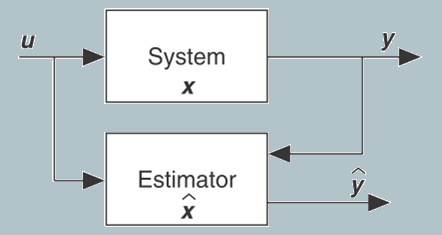

As you see, the estimator is like a parallel system that receives the input and output of the system and generates an estimate of the states. 

Assuem that an input


$$u\left(t\right)=N\omega_{\mathrm{ref}} \left(t\right)$$


is given to the motor, where $N$is the open loop DC gain you computed in Lab05 and $\omega_{\mathrm{ref}} \left(t\right)$is as follows:

T = 10; % Simulation duration
dt = 0.01; % Simulation step time
time = 0:dt:T; % Time array
TStart = 5; % Step start
wRef = zeros(size(time));
wRef(time < TStart) = 25;
wRef(time >= TStart) = 75;
%Plot the reference input here
plot(time,wRef);
grid on;
title(sprintf('Group %d - Input', GroupeNum));
ylim([0, 100])

## *Question 4 (2 marks)*

1. Using the estimator gain obtained above, generate the estimate $\hat{x} \left(t\right)$ of the state. Since we can observe both components of the state, check the accuracy of the estimate by plotting $e\left(t\right)=x\left(t\right)-\hat{x} \left(t\right)$ versus time.

N = 1/30; % my value for the gain from the previous lab was way too large so I used 30.
Motor.reset();
xhat = zeros(2,length(time)); % define a vector to store the estimates
xhat(:,1) = [0;0];  % define the initial condition for estimated values
for n = 1:length(time)
    t_ = time(n);
    w_ = Motor.velocity(t_);
    i_ = Motor.current(t_);
    v_ = wRef(n)*N; % divide the input by the gain you found in Lab05
    if n <=length(time)-1
    % Write the estimator dynamics here
    xhat(:,n+1)=(Gd.A)*xhat(:,n)+(Gd.B)*(N*wRef(n))+L*(w_-Gd.C*xhat(:,n));
    end
    Motor.drive(v_, t_, dt);
    
end
Motor.off();

% Get results of driving Qnet DC Motor
v = Motor.voltage(0, T);
i = Motor.current(0, T);
w = Motor.velocity(0, T);

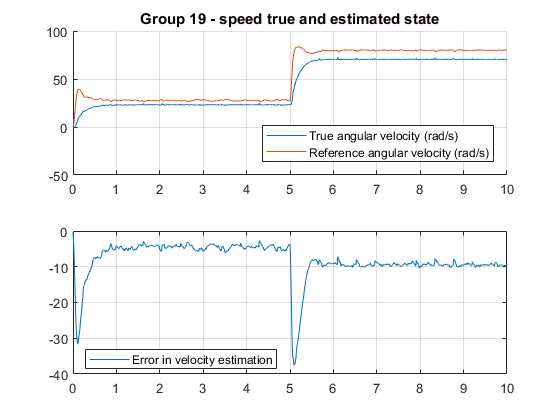

% Plot results
error = [w';i']-xhat;

figure(1); clf;

subplot(2, 1, 1)
title(sprintf('Group %d - speed true and estimated state', GroupeNum));
% Superpose the angular velocity and the the reference $\omega_{ref}$
% plot real speed here
hold on 

plot(time,w)
plot(time, xhat(1,:))
xlim([0, T])
hold off

% plot estimated speed here
legend('True angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'southeast');
xlim([0, T])
grid on

subplot(2, 1, 2)

% plot the error for speed here
plot (time, error(1,:))
legend('Error in velocity estimation', 'location', 'best');
xlim([0, T])
grid on

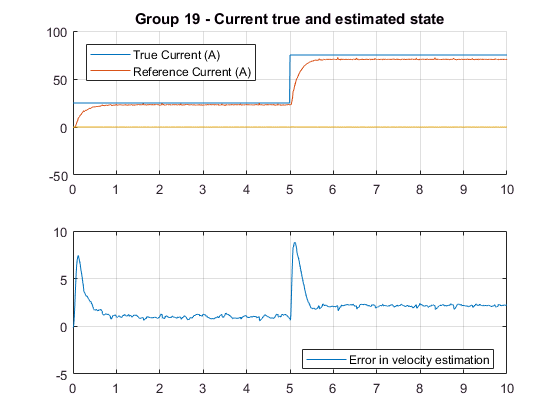


%%===================
% Plot results
figure(2); clf;

subplot(2, 1, 1)
title(sprintf('Group %d - Current true and estimated state', GroupeNum));
% Superpose the angular velocity and the the reference $\omega_{ref}$
% plot real current here
hold on 

plot(time,wRef)
plot(time,w)
plot(time,i)
% plot the estimated current here
legend('True Current (A)', ...
    'Reference Current (A)', ...
    'location', 'northwest');
xlim([0, T])
grid on

subplot(2, 1, 2)
% plot th error for current here
plot (time, error(2,:))
legend('Error in velocity estimation', 'location', 'best');
xlim([0, T])
grid on

 
eigs((Gd.A)-(L)*(Gd.C))

ans =    0.9003 + 0.0903i
   0.9003 - 0.0903i


2. A discrete observer is called asymptotically stable if the observer error $e\left(n\right)=x\left(n\right)-\hat{x} \left(n\right)$ converges to zero when $n\longrightarrow \infty$. For a discrete Luenberger observer, the observer error satisfies $e\left(n+1\right)=\left(A-\mathrm{LC}\right)e\left(n\right)$ and therefore the Luenberger observer for this discrete-time system is asymptotically stable if and only if all of $\mathrm{eig}\left(A-\text{LC}\right)$ are all inside the unit circle around zero for discrete-time systems and in the left-hand plane for continuous time systems. Now, compute the eigenvalues of $\left(A-\text{LC}\right)$ in discrete time and determine whether the observer is asymptotically stable or not. 

Yes, it is asymptotically stable since the eigen values are inside the unit circle.

3. Based on the plot of the error in question 1, does the error go to zero? Does this confirm the asymptotical stability of the observer? If not justify your answer. 

No,  the error does not go to 0 because there is a steady state value at -9.8 which is primarily due to noise. Hence there is no asymptotical stability and the error does not go to 0.